## **Lab 4 Part 1: **

## **System Response Using Matlab / Matlab Simulink**

**Objectives**

Objectives of this lab are to:

1. define the transfer function

2. locate poles and zeros of the system

3. find the system response to unit step and various input functions using both MATLAB command window and MATLAB Simulink.

**Lab Procedure**

After going over the examples provided below, only complete the Lab Exercises. Repeating the examples is highly recommended.

**Transfer Function**

Transfer function is the ratio of the output to the input while all initials of the system is 0. 

Example : 

Define the transfer function in Matlab

num = [2 14];
den = [1 6 20];
G=tf(num,den)

G =
 
     2 s + 14
  --------------
  s^2 + 6 s + 20
 
Continuous-time transfer function.



Find poles and zeros and plotting pole-zero map

pole(G)

ans =   -3.0000 + 3.3166i
  -3.0000 - 3.3166i


zero(G)

ans = -7

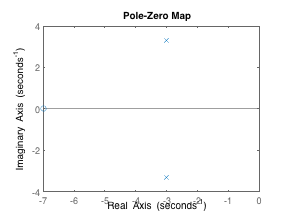

pzmap(G)  % plots the locations of zeroes and poles on the graph

Find the unit impulse and unit step response of the system (or transfer function)

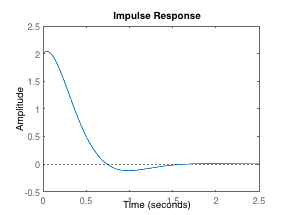

impulse(G) % plots the unit impulse response of the system

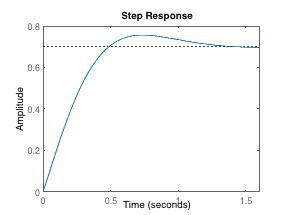

step (G) % plots the unit step response of the system

If you select the figure of the step response of G(s) and click on the arrow, it'd allow you to open the figure in Figure window. Then, right click on the graph and select characteristics, you will be able to find the maximum overshoot, rise time and settling time of the system as shown below.

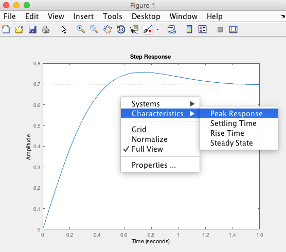

**Simulating Systems**

**1. Matlab Simulink**

Example: Find the step response of the system for r(t)=10*sin(5t) for the same G(s).

**Step 1.** Define transfer function: Select continuous from Simulink Library and then select transfer function and drag it into the model.

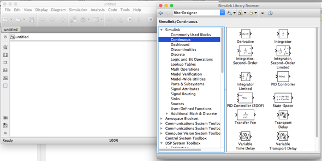

Double click and define the numerator and the denominator of the transfer function.

**Step 2.** Add the input to the model from Sources.

 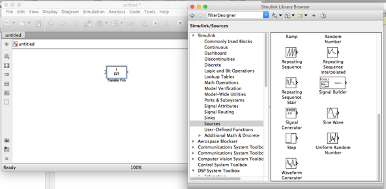

Double click and change the amplitude and the frequency.

 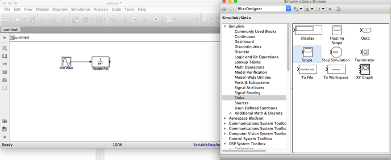

**Step 3.** Add a scope.

**Step 4.** **Before you run the simulation, you might want to change the solver from Variable step to fixed step using ode4 to have a better solution.**

Select Simulations and then configurations and set the followings on your new window. The final model should look like:

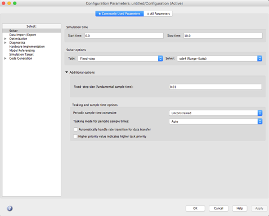

**Step 5.** Once you run the simulation and double click on the scope, you will be able to plot the response of the system:

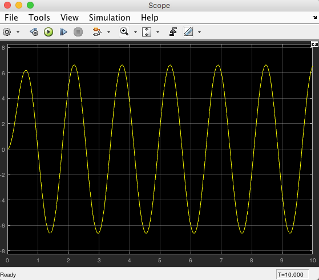

**2. Command Window**

Matlab code to find the response of a system under various inputs:

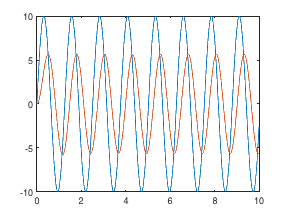

t=0:0.01:10;
r=10*sin(5*t);
c=lsim(G,r,t);
plot(t,r,t,c);

To learn more about lsim, please type on command window.

help lsim

 lsim  Simulate time response of dynamic systems to arbitrary inputs.
 
    lsim(SYS,U,T) plots the time response of the dynamic system SYS to the
    input signal described by U and T. The time vector T is expressed in the
    time units of SYS and consists of regularly spaced time samples. The 
    matrix U has as many columns as inputs in SYS and its i-th row specifies 
    the input value at time T(i). For example, 
            t = 0:0.01:5;   u = sin(t);   lsim(sys,u,t)  
    simulates the response of a single-input model SYS to the input 
    u(t)=sin(t) during 5 time units.
 
    For discrete-time models, U should be sampled at the same rate as SYS
    (T is then redundant and can be omitted or set to the empty matrix).
    For continuous-time models, choose the sampling period T(2)-T(1) small 
    enough to accurately describe the input U.  lsim issues a warning when
    U is undersampled and hidden oscillations may occur.
    

## **Lab Exercise 1**

**For the following systems**


$$G\left(s\right)=\frac{\left(3s+10\right)}{s^2 +4s+7}$$
       
$$H\left(s\right)=\frac{\left(3s+10\right)}{s^2 +7s+10}$$
      
$$I\left(s\right)=\frac{\left(3s+10\right)}{s^2 +9}$$
      
$$J\left(s\right)=\frac{\left(3s+10\right)}{\left(s^2 +6s-10\right)}$$


**1. D**etermine the poles, zeros, pole zero map, and the step response curve of each system.

**2. **Find the response of G(s) to the input signal of r(t)=3*sin(5*t+1)

**3.** Find the response of I(s) to the input signal of a square signal with a period of 5 seconds and the time duration of 100 seconds.

**4. **Find the step response of J(s) using Matlab Simulink and display its output using a scope. 